# 优化

优化最常用的两个函数 fminbnd 以及 fminsearch

问题：函数f(x)是个连续函数，且在指定的**x区间**搜素f最小值时**对应的x**，则可以使用 fminbnd。

注意这里是小于，不是小于等于

方法：x = fminbnd(@scalarobjective,1,3)

## `问题假设`

- `有一个函数f = scalarobjective(x) ，另存为 scalarobjective.m 文件`

- `需要搜索函数在指定范围[1,3]的最小值`

type scalarobjective %显示函数内容，这里仅用于观察

function f = scalarobjective(x)
f = 0;
for k = -10:10
    f = f + (k+1)^2*cos(k*x)*exp(-k^2/2);
end


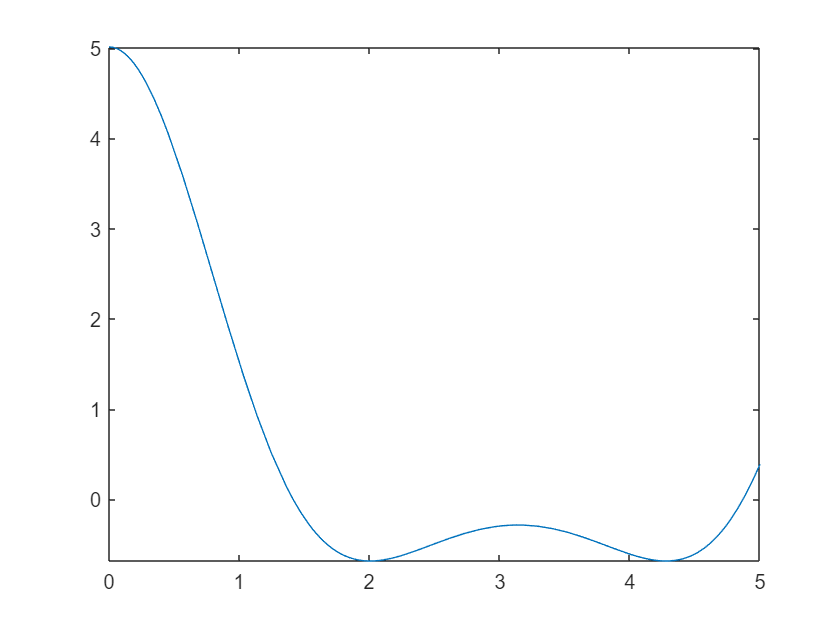

fplot(@scalarobjective,[0,5]) %显示函数曲线，这里仅用于观察

## 搜索目标函数的最优解

也就是f函数最小值时，对应的 x，设定搜索区间为(1,3)

options = optimset('Display','iter');
x = fminbnd(@scalarobjective,1,3,options);% 加option这一项仅仅是为了显示下图过程，否则直接x = fminbnd(@scalarobjective,1,3)

 
 Func-count     x          f(x)         Procedure
    1        1.76393    -0.589643        initial
    2        2.23607    -0.627273        golden
    3        2.52786     -0.47707        golden
    4        2.05121    -0.680212        parabolic
    5        2.03127     -0.68196        parabolic
    6        1.99608    -0.682641        parabolic
    7        2.00586    -0.682773        parabolic
    8        2.00618    -0.682773        parabolic
    9        2.00606    -0.682773        parabolic
   10         2.0061    -0.682773        parabolic
   11        2.00603    -0.682773        parabolic
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 



x = 2.0061

可以，在(1,3)区间内，当 x 取上述值时，f 最小。

此时对应的f最小值为：

f = scalarobjective(x)

f = -0.6828